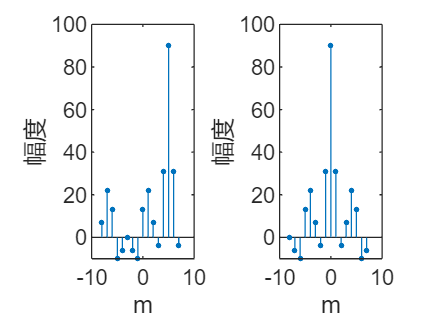

L=16;
x=[2 4 -1 1 7 3 1 -3 0 0 0 0 0 0 0 0];
y=[0 0 0 0 0 2 4 -1 1 7 3 1 -3 0 0 0];
xk = dft(x,L);
yk = dft(y,L);
rxy = real(idft(conj(xk).* yk,L));
rxy =[rxy(L/2 + 1: L) rxy(1: L/2)];
m=(-L/2): (L/2-1);
rxx = real(idft(conj(yk).* yk,L));
rxx = [rxx(L/2 + 1: L) rxx(1: L/2)];
m=(-L/2): (L/2-1);
subplot(121);stem(m,rxy,'.');xlabel( 'm');ylabel('幅度');
subplot(122);stem(m,rxx,'.');xlabel( 'm'); ylabel('幅度');